### Section 2 |


$$x\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
\left\lbrace \begin{array}{ll}
3 & n=0\\
2 & n=1
\end{array}\right. & \\
\left\lbrace \begin{array}{ll}
1 & n=2\\
0 & \textrm{else}
\end{array}\right. & 
\end{array}\right.$$


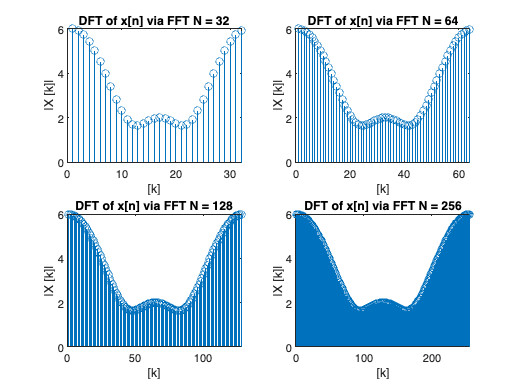

xi = [3 2 1];
ListSizeN = [ 32, 64, 128, 256 ];
ListName = [ "N = 32", "N = 64", "N = 128", "N = 256" ];

figure1 = figure("Name","DFT via FFT");

for i = 1 : length(ListSizeN)
    subplot(2,2, i);
    xi_ = [xi zeros(1,( ListSizeN(i)-length(xi) ) ) ];
    fft_ = fft(xi_);
    stem( abs( fft_ ) );
    xlabel('[k]');
    xlim( [0, ListSizeN(i)] );
    ylabel('|X [k]|');
    title( sprintf("DFT of x[n] via FFT %s", ListName(i)) );
end


$$x\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{ll}
1 & 0\le n\le 6\\
0 & \textrm{else}
\end{array}\right.$$


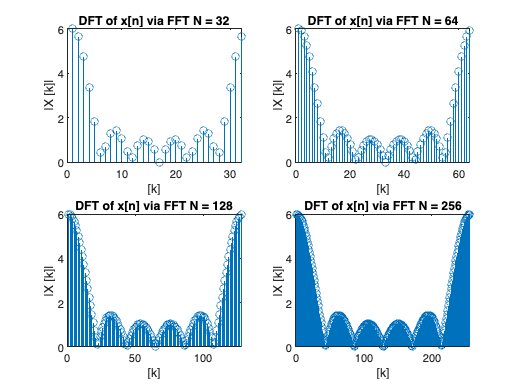

xii = [1, 1, 1, 1, 1, 1];
figure2 = figure("Name","DFT via FFT");

for i = 1 : length(ListSizeN)
    subplot(2,2, i);
    xii_ = [xii zeros(1,( ListSizeN(i)-length(xii) ) ) ];
    fft_ = fft(xii_);
    stem( abs( fft_ ) );
    xlabel('[k]');
    xlim( [0, ListSizeN(i)] );
    ylabel('|X [k]|');
    title( sprintf("DFT of x[n] via FFT %s", ListName(i)) );
end

Comments:

- In both cases of $x\left\lbrack n\right\rbrack$, the results of using Fast Fourier Transform match the results obtained in section 1 by computing the DFT via transform equation.